### Modello

clear all
load('Elicottero.mat')

states = {'u','v','roll rate','pitch rate','roll','pitch','flapping a','flapping b','w','yaw rate','gyroscope yaw rate','paddle c', 'paddle d'};
inputs = {'Lateral cyclic [-1, 1]', 'Longitudinal cyclic [-1, 1]', 'Rudder [-1, 1]', 'Collective pitch [-1, 1]'};
outputs = {'u', 'v', 'w','gyroscope yaw rate'};

C = zeros(4,13);
C(1,strcmp(states, 'u')) = 1;
C(2,strcmp(states, 'v')) = 1;
C(3,strcmp(states, 'w')) = 1;
C(4,strcmp(states, 'gyroscope yaw rate')) = 1;

D = zeros(4,4);
sys = ss(A,B,C,D);
% ,'statename',states,'inputname',inputs,'outputname',outputs
%matrice di trasferimento
G = zpk(tf(sys));
% bode(G), figure, step(G)
Ctr = ctrb(A,B); r_ctr = rank(Ctr,1e-6)

r_ctr = 13

Obs = obsv(A,C); r_obs = rank(Obs,1e-6)

r_obs = 13

## Assegnamento degli autovalori

Metodo itae

omega_n_itae = 2;

p_itae = itae(6,omega_n_itae);

for i=7:13
    p_itae = [p_itae real(p_itae(i-1))-1];
end
disp(p_itae')

  -0.6197 + 2.5267i
  -0.6197 - 2.5267i
  -1.1610 + 1.5657i
  -1.1610 - 1.5657i
  -1.4693 + 0.5745i
  -1.4693 - 0.5745i
  -2.4693 + 0.0000i
  -3.4693 + 0.0000i
  -4.4693 + 0.0000i
  -5.4693 + 0.0000i
  -6.4693 + 0.0000i
  -7.4693 + 0.0000i
  -8.4693 + 0.0000i



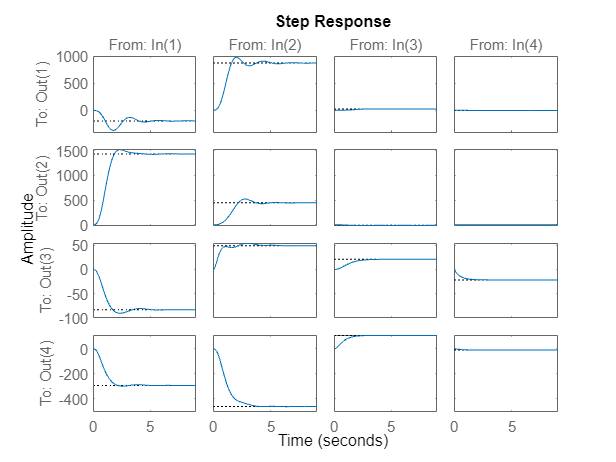

ans = 1.0e+03 *

   -0.1955    0.8724    0.0243   -0.0045
    1.4327    0.4447   -0.0108    0.0008
   -0.0833    0.0491    0.0210   -0.0215
   -0.2918   -0.4610    0.1075   -0.0084


K_itae = place(A,B,p_itae);

CC_itae = ss(A-B*K_itae,B,C,D);

step(CC_itae), dcgain(CC_itae)

### Azione integrale

Aint = [A  zeros(13,4);
        -C zeros(4,4)];
Bint = [B; -D];
Cint = [C, zeros(4,4)];
Dint = D;

Ctr_int = ctrb(Aint,Bint); r_ctr_int = rank(Ctr_int,1e-6)

r_ctr_int = 17

p_int = [p_itae';
         p_itae(end)-0.5;
         p_itae(end)-1;
         p_itae(end)-1.5;
         p_itae(end)-2];
K_int = place(Aint,Bint,p_int);
K_s = K_int(:,1:13);
K_i = K_int(:,14:17);

### Osservatore

p_obs = p_itae.*2;
L = place(A',C',p_obs)';

Aobs = (A-L*C);
Bobs = [B - L*D, L];
Cobs = eye(13);
Dobs = zeros(13,8);

%sim('autovalori_sim.slx')

## Mixed Sensitivity Design

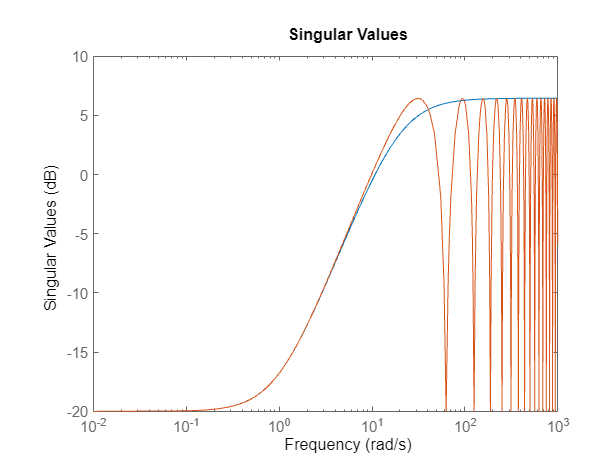

delay = 0.1;

Gt = ss([],[],[],diag([1.1 1.1 1.1 1.1]));
Gt.OutputDelay=delay*ones(1,4);
Greal = Gt*sys;
% bode(G,Greal)
% legend("G","Greal")
Delta=(eye(4)-Gt);
% bode(Delta)
% WT = makeweight(dcgain(Delta(1,1)),1/delay,2.5);
s = tf('s');
WT =  (1 - 1.1*(1-s*delay/2)/(1+s*delay/2)).*eye(4);
sigma(WT,Delta)

### Scelta della Ws

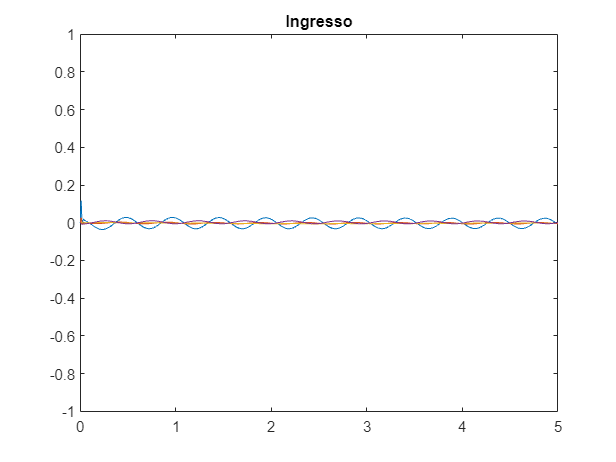

s = tf('s');


% WS = 1e4/(1+s/1e-4)*(1+s/1e-2)/(1+s); %Pironti
WS = 1e8/(1+s/1e-6)*(1+s/1e-0)/(1+s/1e2)^2.*eye(4); %va benissimo col filtro su X e Y ma non è robusto
WS(3,3) = 1e4/(1+s/1e-5);
WS(4,4) = 1e4/(1+s/1e-5);
WK = tf(1e0.*diag([1 1 1 1]).*0.2);
%WK(1,1) = 10;
[K_inf,CL,GAM,INFO] = mixsyn(sys,WS,WK,WT);

out = sim('H_inf_sim.slx');
plot(out.u.time,out.u.signals.values);
title('Ingresso')
axis([0 5 -1 1])

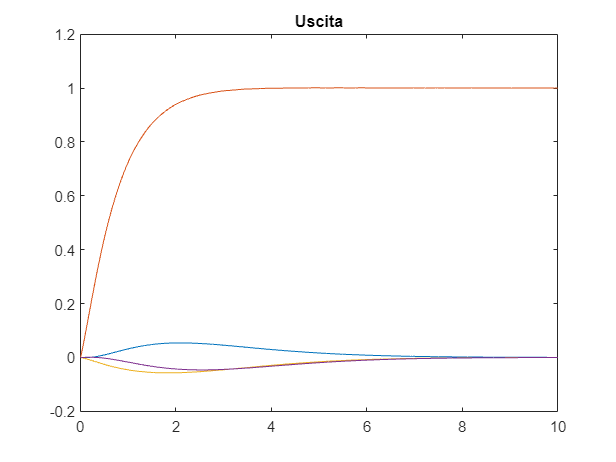

plot(out.y.time,out.y.signals.values);
title('Uscita')

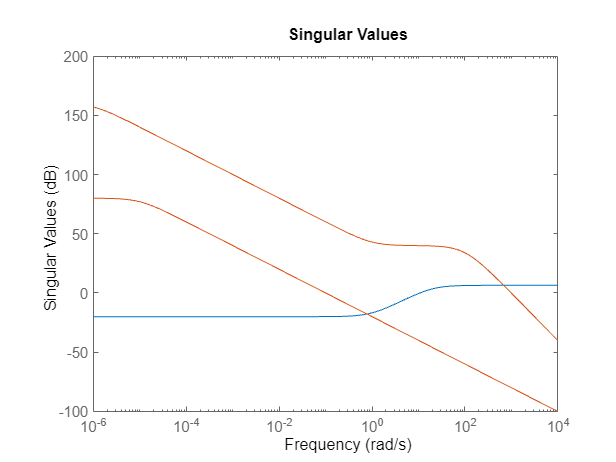


L = G*K_inf;
S = feedback(eye(4),L);
T = feedback(L,eye(4));
sigma(WT,WS)

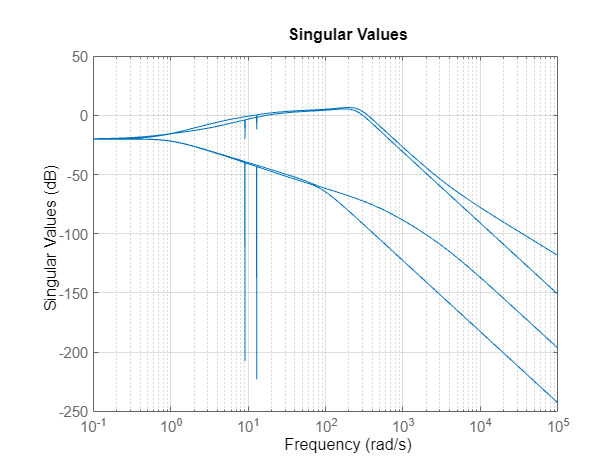

% sigma(WK)
% sigma(T)
% sigma(K_inf*S)
sigma(WT*T),grid

## Controllo LQ

Q = diag([1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 1; 0.3; 0.3; 0.3; 0.3]).*1;
R = diag([1; 1; 1; 1]);
[K_lq, S, eig_LQ] = lqr(Aint, Bint,Q,R);
K_s_lq = K_lq(:,1:13);
K_i_lq = K_lq(:,14:17);

## Controllo LQG

BandWidth=100;
NoisePower=1e-6/BandWidth;
Rt=eye(4)*NoisePower;
Qt=eye(13)*1e-20;

L_kalman = lqr(A',C',Qt,Rt)';
A_k = (A-L_kalman*C);
B_k = [B - L_kalman*D, L_kalman];
C_k = eye(13);
D_k = zeros(13);
